# Modelo climático de Lorenz

El modelo de Lorenz representa el fenómeno de [convección atmosférica](https://es.wikipedia.org/wiki/Convecci%C3%B3n_atmosf%C3%A9rica), la cual es el resultado de la diferencia de temperatura en las capas atmosféricas: una mezcla de aire durante el día expande la altura de la capa límite planetaria provocando corrientes de aire, desarrollando cúmulos y una disminución de los puntos de rocío de la superficie. La convección húmeda provoca el desarrollo de tormentas eléctricas, incluyendo granizo, vientos fuertes y tornado.


$$\dot{x} = \sigma (y-x)\\
\dot{y} = x(\rho -z)-y\\
\dot{z} = xy-\beta z$$


$x:$ es la tasa de convección (velocidad del fluido circular, rotación del anillo)

$y:$ es la variación de temperatura horizontal

$z:$ es la variación de temperatura vertical

$\sigma :$ es la viscosidad

$\rho :$ es la transferencia de calor (diferencia de temperatura entre la base y el tope)

$\beta :$ representa el tamaño físico (relación entre la longitud y altura).

Valor de los parámetros para este caso de estudio: $\sigma = 10$, $\rho = 28$, $\beta = \frac{8}{3}$

**Extra:** calculo de puntos de equilibrio

syms x y z
syms sigma rho beta

f = [sigma*(x-y)==0;
    x*(rho - z)-y==0;
    x*y-beta*z==0];
EquilibriosSym = solve(f);

%Puntos de equilibrio del modelo Lorenz
EquilibriosSym.x, EquilibriosSym.y, EquilibriosSym.z

$$ans = \left(\begin{array}{c} 0\\ -\sqrt{\beta \,\left(\rho -1\right)}\\ \sqrt{\beta \,\left(\rho -1\right)} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ -\sqrt{\beta \,\left(\rho -1\right)}\\ \sqrt{\beta \,\left(\rho -1\right)} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ \rho -1\\ \rho -1 \end{array}\right)$$

%Puntos de equilibrio del modelo Lorenz evaluados para caso de estudio
Equilibrios = subs(EquilibriosSym,{sigma rho beta},{10 28 8/3});
eqX = Equilibrios.x, eqY = Equilibrios.y, eqZ = Equilibrios.z

$$eqX = \left(\begin{array}{c} 0\\ -\frac{\sqrt{3}\,\sqrt{712}}{3}\\ \frac{\sqrt{3}\,\sqrt{712}}{3} \end{array}\right)$$

$$eqY = \left(\begin{array}{c} 0\\ -\frac{\sqrt{3}\,\sqrt{712}}{3}\\ \frac{\sqrt{3}\,\sqrt{712}}{3} \end{array}\right)$$

$$eqZ = \left(\begin{array}{c} 0\\ 89\\ 89 \end{array}\right)$$

Note que hay tres puntos de equilibrio:


$$P_1 = (0,0,0)$$



$$P_2 = \left(-\sqrt{72},-\sqrt{72}, 27\right)$$



$$P_3 = \left(\sqrt{72},\sqrt{72}, 27 \right)$$


## 1. Simulación temporal

Observar el aparente comportamiento estocástico, cuando realmente es determinístico.

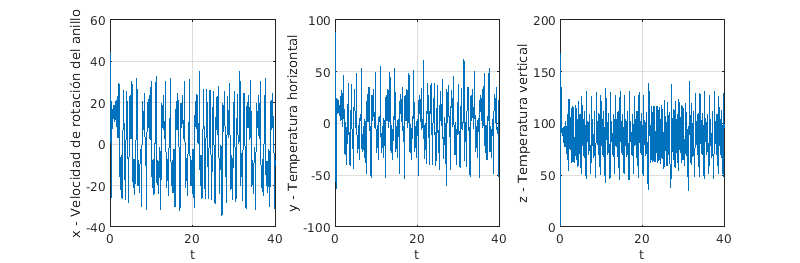

syms x(t) y(t) z(t)

%parámetros
sigma = 10; rho = 28; beta = 8/3;

%Ecuaciones diferenciales
f1 = sigma*(y - x);                         %Convección
f2 = x*(rho - z) - y;                       %Temperatura horizontal
f3 = x*y - beta*z;                          %temperatura vertical
f = odeFunction([f1 f2 f3],[x y z]);

%Método numérico
h1 = 0.01;                                  %Tamaño del paso
tmax = 100;                                 %Tiempo final de simulación
tspan = 0:h1:tmax;                          %Tiempo de simulación
ci = [1 1 1];                               %Condiciones iniciales
[t,sol] = ode45(f,tspan,ci);                %Método numérico
x = sol(:,1); y = sol(:,2); z = sol(:,3);   %Renombrar las soluciones del sistema para graficar
tlim = 40;

%Graficar la solución
Fig1 = figure;
subplot(1,3,1)
    plot(t,x)
    grid on
    xlim([0 tlim])
    xlabel('t')
    ylabel('x - Velocidad de rotación del anillo')

subplot(1,3,2)
    plot(t,y)
    xlim([0 tlim])
    grid on
    xlabel('t')
    ylabel('y - Temperatura horizontal')

subplot(1,3,3)
    plot(t,z)
    xlim([0 tlim])
    grid on
    xlabel('t')
    ylabel('z - Temperatura vertical')

%Mejorar visualización de los subplots (Linea de código para estética)    
set(Fig1,'Units','normalized','Position',[0 0 1 0.5]);

## 2. Cambio de las condiciones iniciales

El caos es un fenómeno determinístico que se presenta en ciertos sistemas dinámicos no lineales de tiempo continuo o discreto y que se manifiesta como una sensibilidad extrema de la respuesta temporal a las condiciones iniciales (el llamado efecto mariposa) y que hace que la salida del sistema sea impredecible a largo plazo. Observar el problema de sensibilidad a las condiciones iniciales: el [efecto mariposa](https://es.wikipedia.org/wiki/Efecto_mariposa).

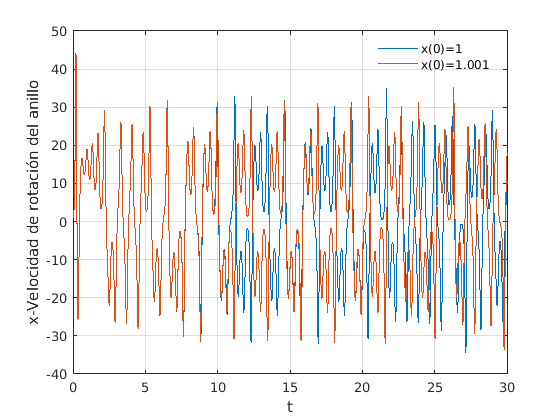

%Condiciones iniciales
ci = [1.001 1 1]; 

%Solución numérica
[t1,sol1] = ode45(f,tspan,ci);

%gráfica de la solución
figure
plot(t,sol(:,1))
hold on
grid on
plot(t1,sol1(:,1))
xlim([0 30])
xlabel('t')
ylabel('x-Velocidad de rotación del anillo')
legend({'x(0)=1','x(0)=1.001'},'Location','best','box','off')

## 3. Espacio de estado de 3 dimensiones

Un sistema caótico tiene un comportamiento que lo lleva a ciertas figuras geométricas densas en el espacio de estado llamadas [**atractores extraños**](https://es.wikipedia.org/wiki/Atractor#Atractor_extra%C3%B1o), siempre que las condiciones iniciales estén dentro de una zona llama región de atracción. Un punto de equilibrio o un ciclo límite son **atractores predecibles**. Al final, el sistema estará confinado a cierta región del espacio de estado que rodea los atractores. De esta manera, un atractor es un conjunto de valores numéricos de las variables de estado hacia los que tiende a evolucionar un sistema caótico para una amplia gama de condiciones iniciales. 

Observar la presencia de un atractor extraño en el espacio de estado del modelo de Lorenz (hacer clic en la figura y hacer clic en el ícono de rotación de la figura para ver la figura 3D desde diferentes perspectivas:  . El atractor es cada una de las zonas en las cuales la trayectoria de estado oscila ("cada una de las alas de la mariposa").

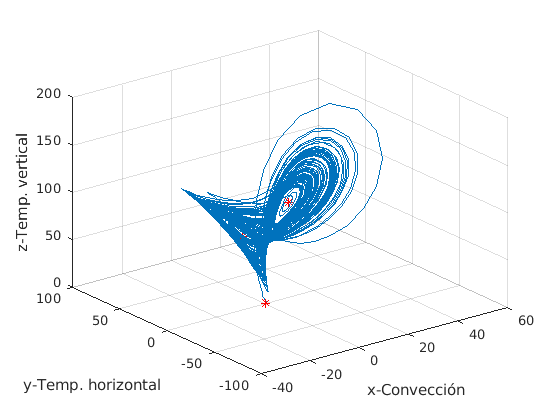

figure
plot3(x,y,z)
hold on
plot3(eqX,eqY,eqZ,'r*')
xlabel('x-Convección')
ylabel('y-Temp. horizontal')
zlabel('z-Temp. vertical')
grid on

Perspectiva en cada una de las caras del espacio de estado:

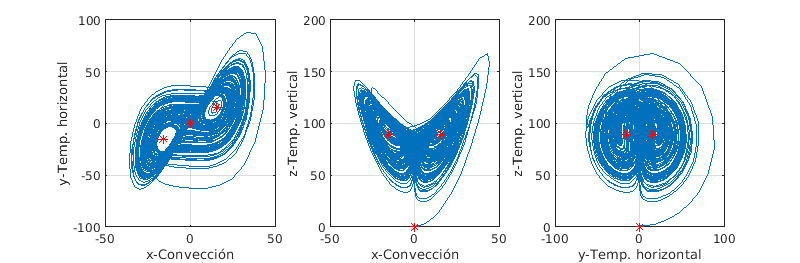

Fig3 = figure;

subplot(1,3,1)  
    plot(x,y)
    hold on 
    plot(eqX,eqY,'r*')
    xlabel('x-Convección')
    ylabel('y-Temp. horizontal')
    grid on

subplot(1,3,2)
    plot(x,z)
    hold on 
    plot(eqX,eqZ,'r*')
    xlabel('x-Convección')
    ylabel('z-Temp. vertical')
    grid on

subplot(1,3,3)
    plot(y,z)
    hold on 
    plot(eqY,eqZ,'r*')
    xlabel('y-Temp. horizontal')
    ylabel('z-Temp. vertical')
    grid on

%Mejorar visualización de los subplots (Linea de código para estética)   
set(Fig3,'Units','normalized','Position',[0 0 1 0.5]);

## 4. Cambio del parámetro $\rho = 20$

**Extra:** puntos de equilibrio

syms x y z
syms sigma rho beta

f = [sigma*(x-y)==0;
    x*(rho - z)-y==0;
    x*y-beta*z==0];
EquilibriosSym = solve(f);

%Puntos de equilibrio del modelo Lorenz
EquilibriosSym.x, EquilibriosSym.y, EquilibriosSym.z

$$ans = \left(\begin{array}{c} 0\\ -\sqrt{\beta \,\left(\rho -1\right)}\\ \sqrt{\beta \,\left(\rho -1\right)} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ -\sqrt{\beta \,\left(\rho -1\right)}\\ \sqrt{\beta \,\left(\rho -1\right)} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0\\ \rho -1\\ \rho -1 \end{array}\right)$$

Equilibrios = subs(EquilibriosSym,{sigma rho beta},{10 20 8/3});
eqX = Equilibrios.x, eqY = Equilibrios.y, eqZ = Equilibrios.z

$$eqX = \left(\begin{array}{c} 0\\ -\frac{\sqrt{3}\,\sqrt{152}}{3}\\ \frac{\sqrt{3}\,\sqrt{152}}{3} \end{array}\right)$$

$$eqY = \left(\begin{array}{c} 0\\ -\frac{\sqrt{3}\,\sqrt{152}}{3}\\ \frac{\sqrt{3}\,\sqrt{152}}{3} \end{array}\right)$$

$$eqZ = \left(\begin{array}{c} 0\\ 19\\ 19 \end{array}\right)$$

**Simulación:**

syms x(t) y(t) z(t)
%Parámetros
sigma = 10; rho = 20; beta = 8/3;

%Ecuaciones diferenciales
f1 = sigma*(y - x);                         %Convección
f2 = x*(rho - z) - y;                       %Temperatura horizontal
f3 = x*y - beta*z;                          %temperatura vertical
f = odeFunction([f1 f2 f3],[x y z]);

%Método numérico
h1 = 0.01;                                  %Tamaño del paso
tmax = 100;                                 %Tiempo final de simulación
tspan = 0:h1:tmax;                          %Tiempo de simulación
ci = [1 1 1];                               %Condiciones iniciales
[t,sol] = ode45(f,tspan,ci);                %Método numérico
x = sol(:,1); y = sol(:,2); z = sol(:,3);   %Renombrar las soluciones del sistema para graficar
tlim = 40;

Respuesta temporal:

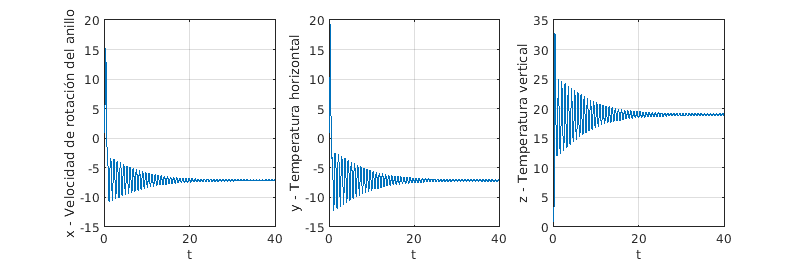

h1 = figure;
subplot(1,3,1)
    plot(t,x)
    xlim([0 tlim])
    grid on
    xlabel('t')
    ylabel('x - Velocidad de rotación del anillo')
subplot(1,3,2)
    plot(t,y)
    xlim([0 tlim])
    grid on
    xlabel('t')
    ylabel('y - Temperatura horizontal')
subplot(1,3,3)
    plot(t,z)
    xlim([0 tlim])
    grid on
    xlabel('t')
    ylabel('z - Temperatura vertical')

%Mejorar visualización de los subplots (Linea de código para estética) 
set(h1,'Units','normalized','Position',[0 0 1 0.5]);

Cambio de la condición inicial:

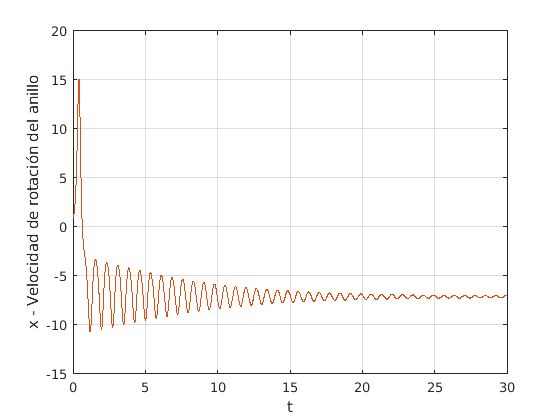

%Cambio condiciones iniciales
ci = [1.001 1 1];

%Solución numérica
[t1,sol1] = ode45(f,tspan,ci); 

%gráfico de la solución
h4 = figure;
plot(t,sol(:,1),t1,sol1(:,1))
xlim([0 30])
grid on
xlabel('t')
ylabel('x - Velocidad de rotación del anillo')

Espacio de estado de tres dimensiones (se tiende claramente a un centro, el cual se puede observar al hacer zoom):

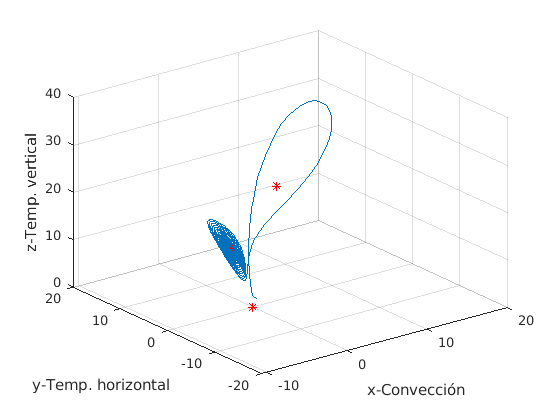

figure
plot3(x,y,z)
hold on
plot3(eqX,eqY,eqZ,'r*')
xlabel('x-Convección')
ylabel('y-Temp. horizontal')
zlabel('z-Temp. vertical')
grid on

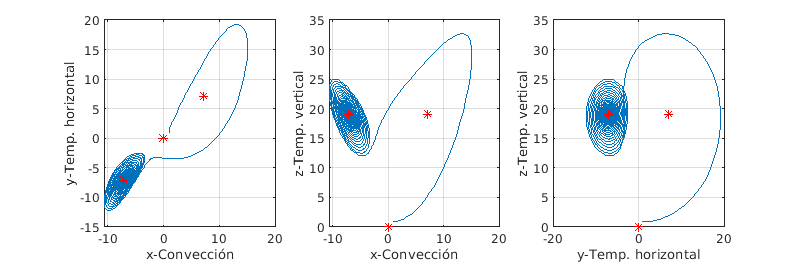

Fig3 = figure;
subplot(1,3,1)  
    plot(x,y)
    hold on 
    plot(eqX,eqY,'r*')
    xlabel('x-Convección')
    ylabel('y-Temp. horizontal')
    grid on

subplot(1,3,2)
    plot(x,z)
    hold on 
    plot(eqX,eqZ,'r*')
    xlabel('x-Convección')
    ylabel('z-Temp. vertical')
    grid on

subplot(1,3,3)
    plot(y,z)
    hold on 
    plot(eqY,eqZ,'r*')
    xlabel('y-Temp. horizontal')
    ylabel('z-Temp. vertical')
    grid on

set(Fig3,'Units','normalized','Position',[0 0 1 0.5]);